# Calcul de tensions: dit ortopèdic

DiAM, 2017-2022

clear, close all

## Dades del problema

l = 53;     % [mm] distància entre la forca (F2) i la secció més propera a B
b = 27;     % [mm] distància entre la forca (F1) i la secció més propera a B
D =  8;     % [mm] diàmetre exterior de la secció a analitzar
t_= [1:0.1:3];% [mm] gruix perfil circular de 1 a 3 mm

F1 = 190;   % [N]  força aplicada F1
F2 = 30;    % [N]  força aplicada F2

## **Càlcul de les sol.licitacions sobre la secció C-C**

**Situació de la secció C-C** 

Les distàncies que es consideren pels moments flectors i torsors són: $b$ i $l$. L'eix 'x' es considera el longitudinal a la seccio C-C, el 'z' el vertical (mateixa direcció de $F_2$) i el 'y' l'horitzontal.

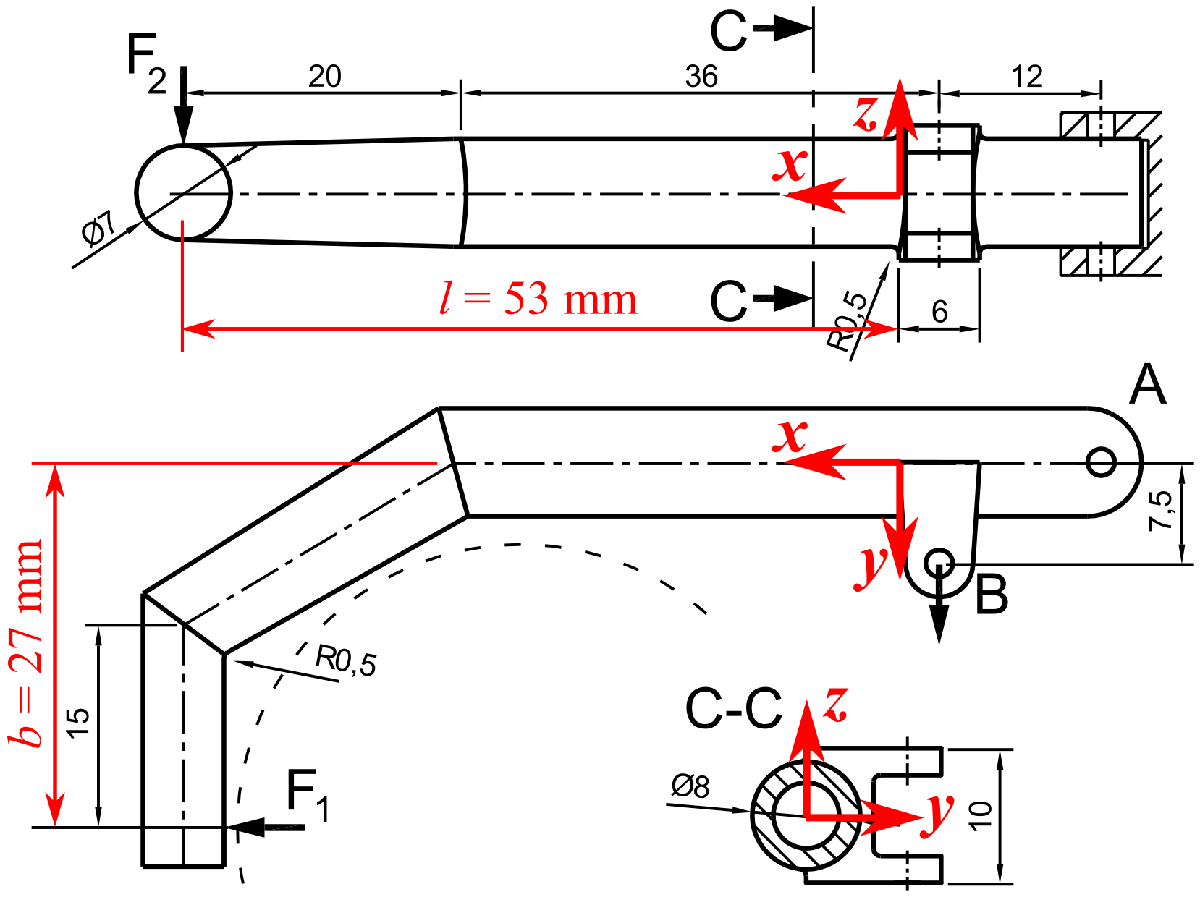

Les sol·licitacions a la secció d'estudi són:

N =   F1;   % forca axial a la seccio
V_z = F2;   % forca tallant en l'eix z a la seccio
M_z = b*F1; % moment creat en l'eix z
M_y = l*F2; % moment creat en l'eix y
T_x = b*F2; % torsor creat en l'eix x

A partir d'aquest punt del codi es calcula per tots els valors de $t$

i_gruix = 1;
for t = t_ % variacio del gruix 
    

#### Càlcul de les propietats de la secció C-C

d = D-2*t;              % Diametre interior

A = (pi/4)*(D^2-d^2);   % Area de la seccio
I = (pi/64)*(D^4-d^4);  % Moment de segon ordre de la seccio circular
J = (pi/32)*(D^4-d^4);  % Moment de segon ordre polar de la seccio circular

r= D/2;                 % Distancia maxima linia neutre / centroide

## Estudi dels punts crítics

S'identifiquen tres punts crítics a la secció: 'a', 'b' i 'c'. El punt 'a' és el superior de la secció, el punt 'b' està situat a la línia horitzonal i el punt 'c' és el que rep el màxim moment flector.

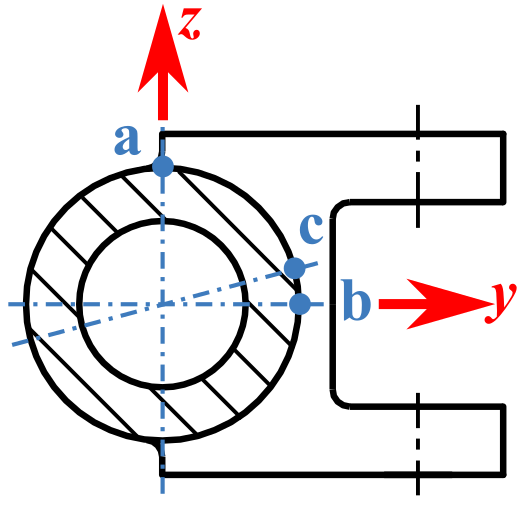

## Tensions en el punt 'a'

Rep un esforç normal causat per la força axial i el moment, i un esforç tallant resultat del moment de torsió.

sig_N = N/A;           % Tensio normal de la forca axial en el punt a
sig_M = M_y*r/I;       % Tensio normal del moment flector en el punt a
tau_T = T_x*r/J;       % Tensio tallant del torsor en el punt a

[sig_A(i_gruix,1),sig_B(i_gruix,1),tau_max(i_gruix,1),sig_VM(i_gruix,1)]=f_invariants2D(sig_M+sig_N,0,tau_T);

## Tensions en el punt 'b'

Rep un esforç normal causat per la força axial i el moment, i un esforç tallant resultat del moment torsor i la força tallant.

sig_N = N/A;        % Tensio normal de la forca axial en el punt b
tau_V = 2*V_z/A;    % Tensio tallant de la forca tallant en el punt b
sig_M = M_z*r/I;    % Tensio normal del moment flector en el punt b
tau_T = T_x*r/J;    % Tensio tallant del torsor en el punt b

[sig_A(i_gruix,2),sig_B(i_gruix,2),tau_max(i_gruix,2),sig_VM(i_gruix,2)]=f_invariants2D(sig_M+sig_N,0,tau_T+tau_V);

## Tensions en el punt 'c'

Està situat en el punt de màxim esforç causat pel moment flector. Rep un esforç normal causat per la força axial i el moment flector combinat i un esforç tallant resultat del moment de torsió. També rep un petit esforç tallant causat per la forca tallant que es pot menystenir.

phi = atan2(M_y,M_z);           % rad, valor de l'angle quan les tensions normals son maximes

sig_N = N/A;                    % Tensio normal de la forca radial 
sig_M= ((M_y^2+M_z^2)^.5)*r/I;  % Tensio normal del moment flector
tau_V= 0;                       % Tensio tallant [o tambe aproximadament = (2*V_z/A)*sin(phi)]
tau_T= T_x*r/J;                 % Tensio tallant del torsor

[sig_A(i_gruix,3),sig_B(i_gruix,3),tau_max(i_gruix,3),sig_VM(i_gruix,3)]=f_invariants2D(sig_M+sig_N,0,tau_T+tau_V);

i_gruix=i_gruix+1;% Increment del comptador per guardar el vector de les tensions i tallants.
end

## Cercles de Mohr en cada punt (del primer i últim gruix calculat)

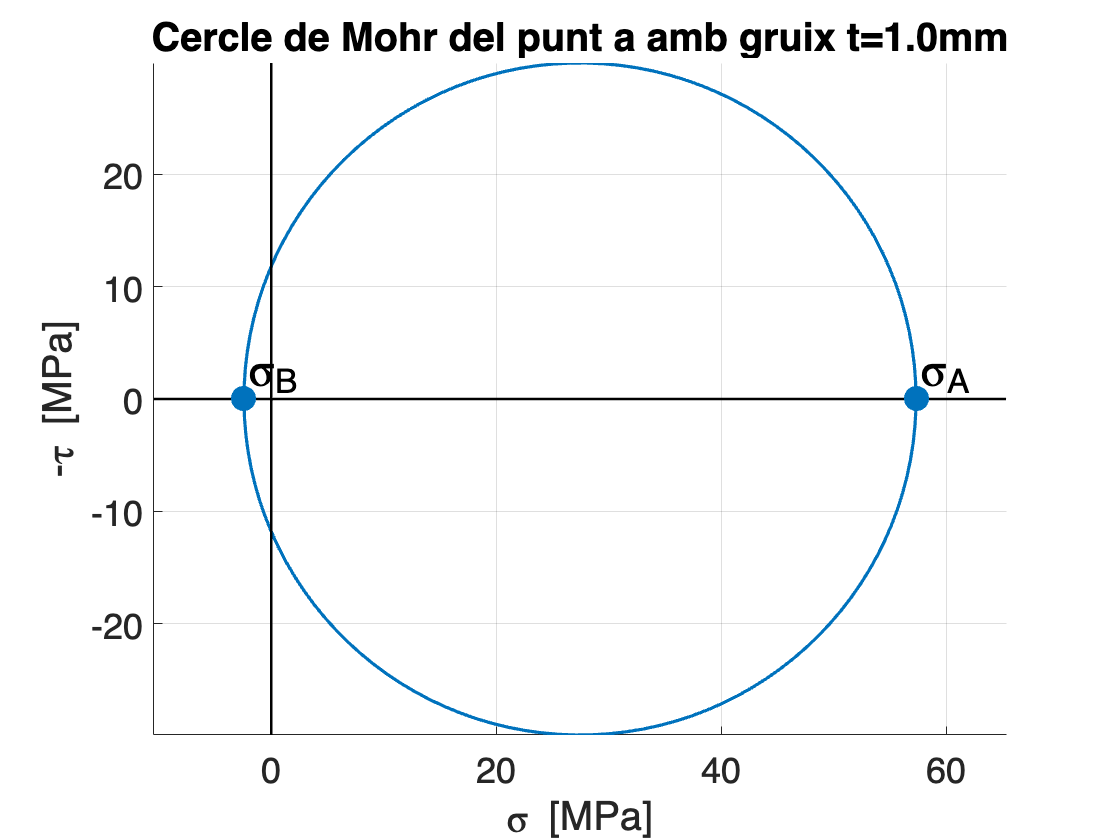

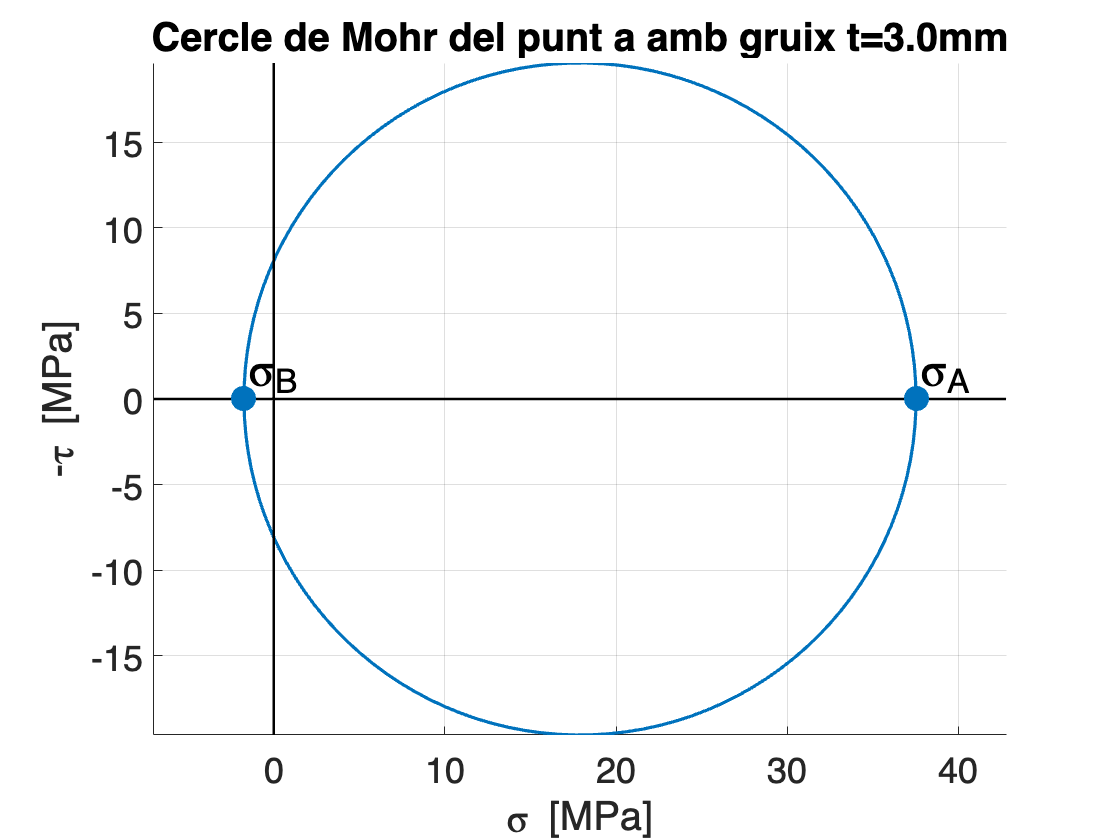

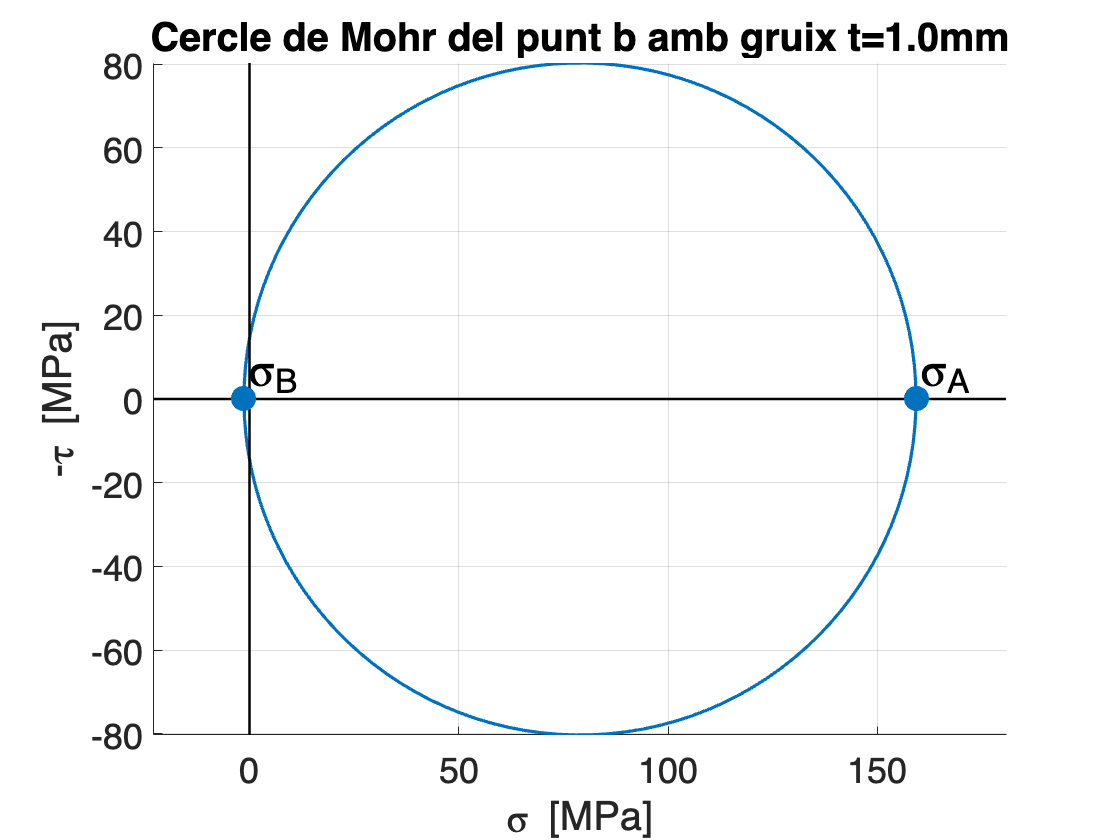

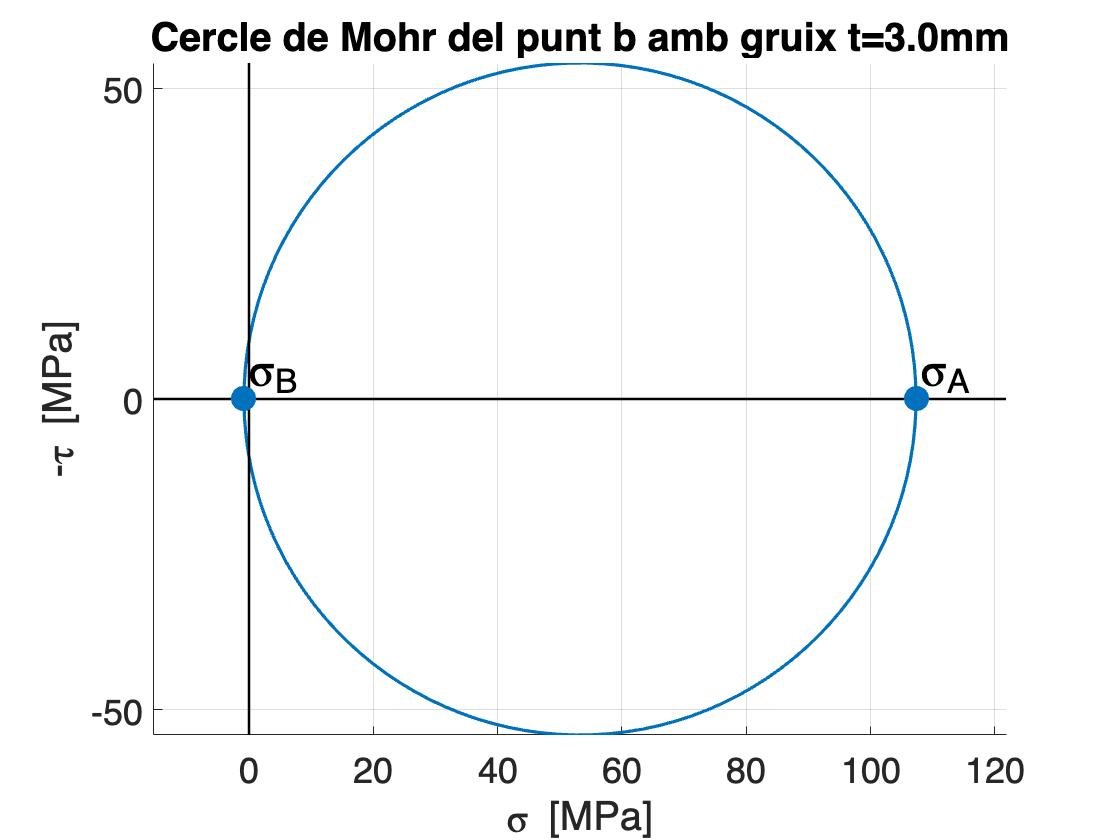

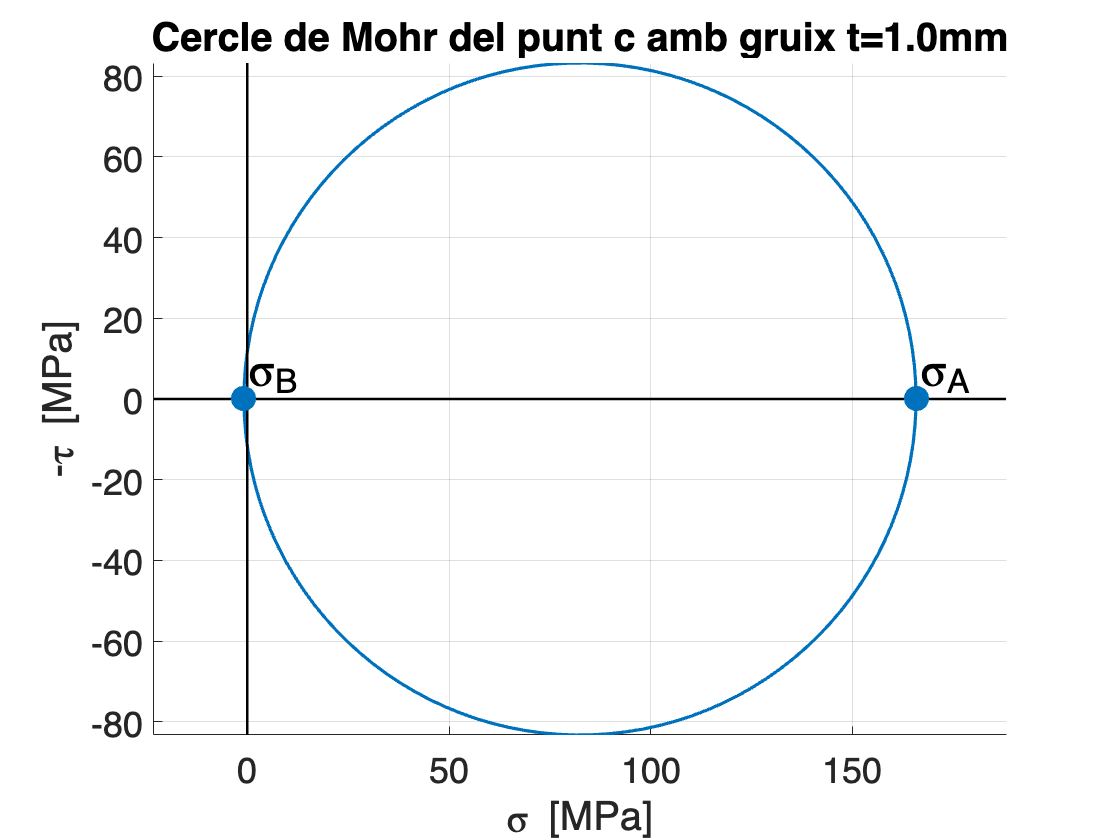

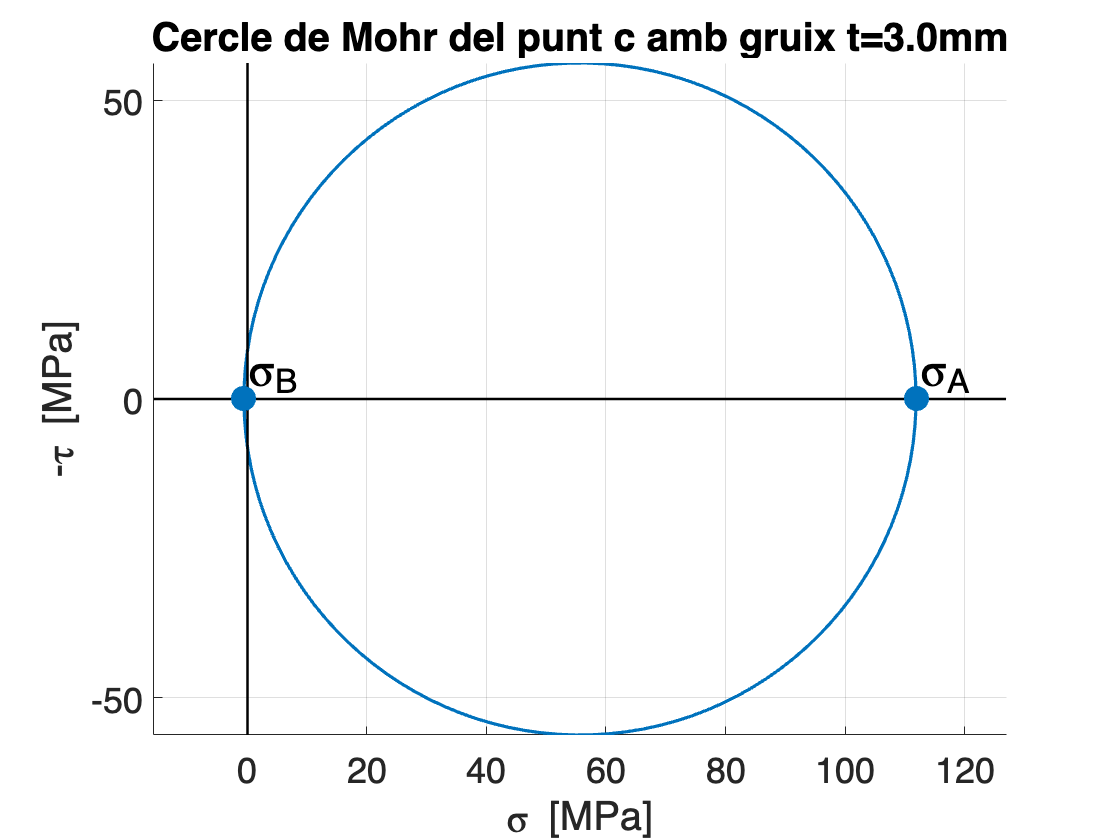

desc_punt =['a','b','c'];
for i_punt = [1:3]
    f_cercle_Mohr2D(sig_A(1,i_punt),sig_B(1,i_punt),desc_punt(i_punt),t_(1));
    f_cercle_Mohr2D(sig_A(end,i_punt),sig_B(end,i_punt),desc_punt(i_punt),t_(end));
end

## Diagrames de les tensions en funció del gruix $t$

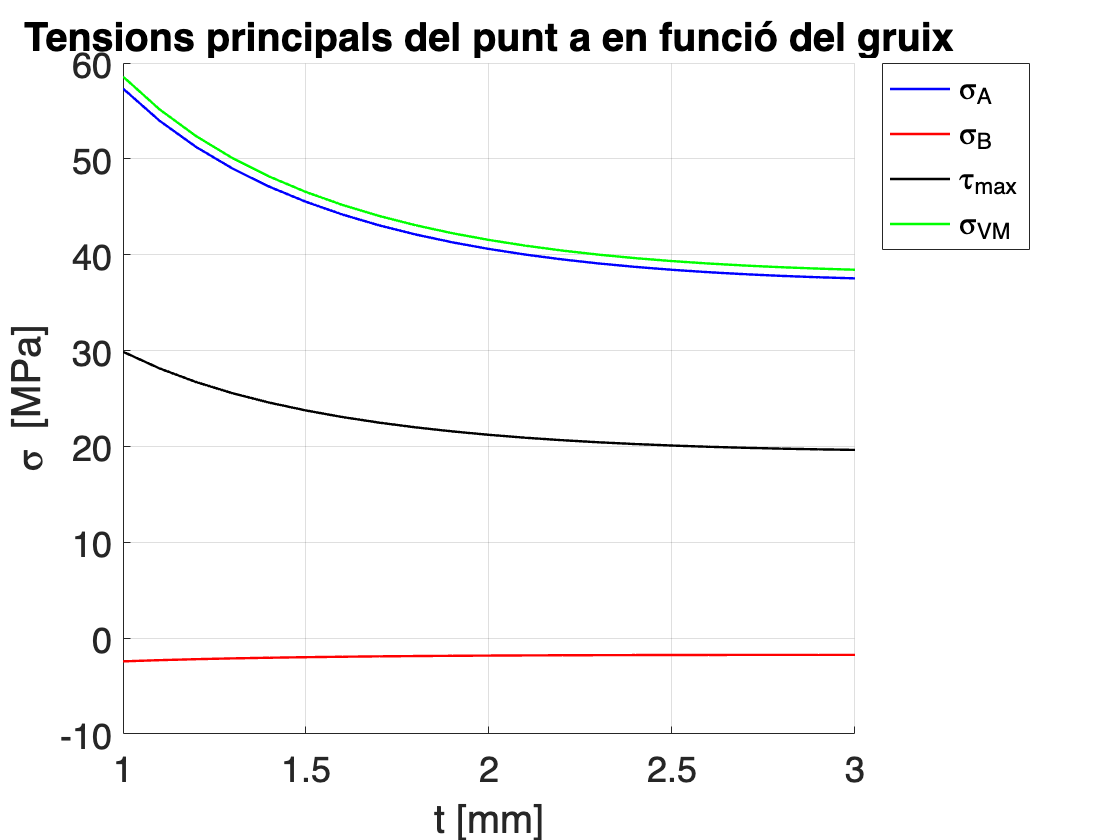

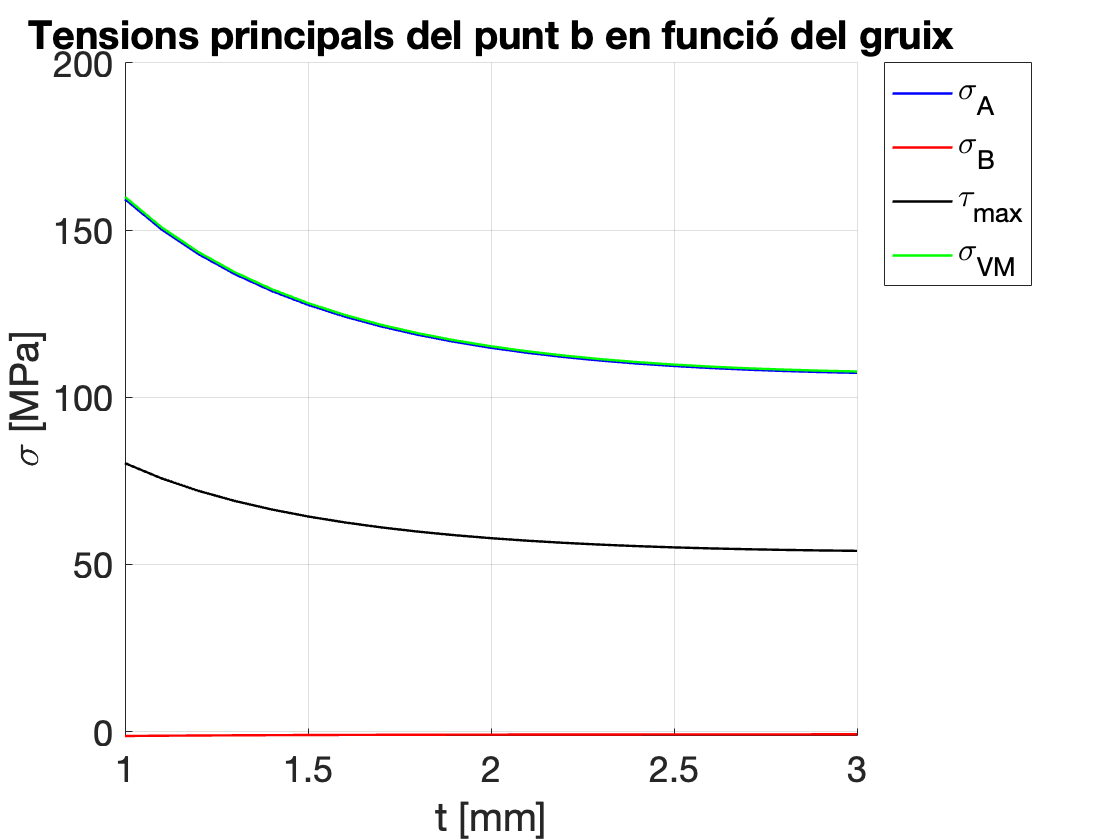

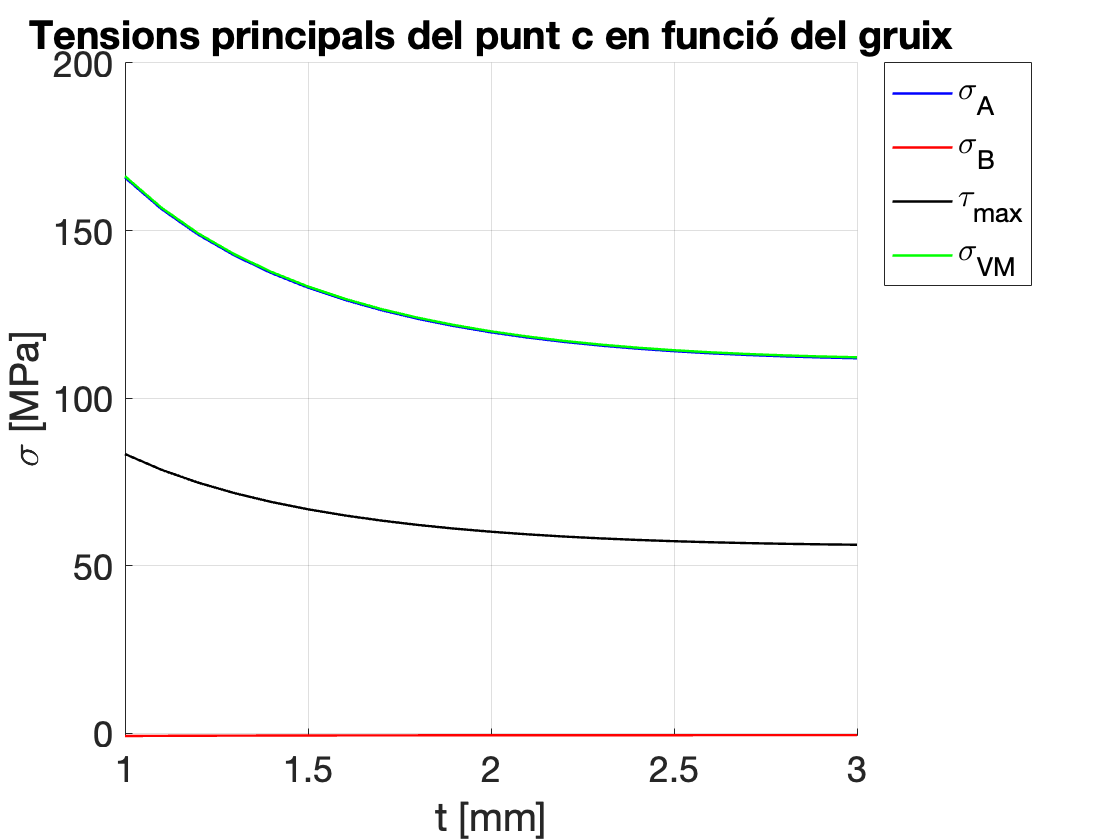

desc_punt =['a','b','c'];
for i_punt = [1:3]
    f_grafic(t_,sig_A(:,i_punt),sig_B(:,i_punt),tau_max(:,i_punt),sig_VM(:,i_punt),...
             desc_punt(i_punt));
end

## Discusió dels resultats

El punt 'c' és el punt més crític en qualsevol gruix entre $t$=1.0 mm i 3.0 mm, on la hípòtesi de desestimar l'esforç causat per la força tallant és correcte (valor de tallant màxim al voltant de 60 MPa i el valor d'aquest esforç tallant inferior a 1.6 MPa)

La tensió dominant en tots els punts és la tensió en la direcció longitudinal a tracció.

L'evolució de la tensió respecte el gruix és clarament no-lineal. Això és a causa de que la tensió dominant és la produïda principalment per la flexió de l'element.

## Definició de funcions

function [sig_A,sig_B,tau_max,sig_VM] =f_invariants2D (sigX, sigY, tauXY)
%f_invariants2D Aquesta funció calcula 4 invariants d'un estat de tensió
%               plana (bidimensional):
%               sig_A  : tensió principal màxima en el pla
%               sig_B  : tensió principal mínima en el pla
%               tau_max: tallant màxim
%               sig_VM : tensió equivalent de von Mises
% Els resultats surten ordenats a la variable 'invariants'

sig = sort(eig([sigX     tauXY;
                tauXY    sigY ]),'descend'); 
sig_A = sig(1); % Tensio principal A
sig_B = sig(2); % Tensio principal B
tau_max= 0.5*(sig(1)-sig(2)); % Tallant maxim
sig_VM = sqrt(((sig(1))^2)+((sig(2))^2)-(sig(1)*sig(2))); % Tensio Von Mises
end

function f_cercle_Mohr2D(sigma_A,sigma_B,desc_punt,t)
% Representa el cercle de Mohr d'un estat de tensió plana (bidimensional)
% inputs:   sigma_A  : tensió principal màxima en el pla
%           sigma_B  : tensió principal mínima en el pla
%           desc_punt, etiqueta del punt representat
%           t, gruix en mm de la secció

figure;hold on;grid on;axis equal;set(gca,'FontSize',18);
theta = 0 : 0.05 : 2*pi;
%cercle sigmaI-sigmaII
plot((sigma_A-sigma_B)/2 * cos(theta) + (sigma_A+sigma_B)/2,...
    (sigma_A-sigma_B)/2 * sin(theta),'Color',[0, 0.4470, 0.7410],'LineWidth',1.6);
% dibuixa eixos
line([0 0], ylim,'Color','k','LineWidth',1.2);  %y-axis
line(xlim, [0 0],'Color','k','LineWidth',1.2);  %x-axis
% dibuixa punts
plot([sigma_A sigma_B],[0 0],'o','MarkerEdgeColor',[0, 0.4470, 0.7410],...
        'MarkerFaceColor',[0, 0.4470, 0.7410],'MarkerSize',12);
% Escriu anotacions
y_lim = ylim;gap = y_lim(2)/12;
text(sigma_A,+gap,'\sigma_{A}','FontSize',24);
text(sigma_B,+gap,'\sigma_{B}','FontSize',24);
xlabel('\sigma [MPa]');ylabel('-\tau [MPa]');
title(['Cercle de Mohr del punt ',desc_punt,' amb gruix t=',num2str(t,'%.1f'),'mm']); 
end

function f_grafic (t_,sig_A,sig_B,tau_max,sig_VM,desc_punt)
%f_grafic Aquesta funció dibuixa evolució tensions quan canvia el gruix

figure();set(gca,'FontSize',18);
hold on; % Serveix per poder dibuixar en el mateix grafic varies tensions
grid on; % Comanda per activar la malla dels eixos
plot(t_',sig_A,'-b','LineWidth',1.2);   % Comanda per dibuixar la grafica 
plot(t_',sig_B,'-r','LineWidth',1.2);   % Comanda per dibuixar la grafica
plot(t_',tau_max,'-k','LineWidth',1.2); % Comanda per dibuixar la grafica
plot(t_',sig_VM,'-g','LineWidth',1.2);  % Comanda per dibuixar la grafica
xlabel('t [mm]');ylabel('\sigma [MPa]'); 
legend('\sigma_{A}','\sigma_{B}','\tau_{max}','\sigma_{VM}',...
       'Location','northeastoutside');
title(['Tensions principals del punt ',desc_punt,' en funció del gruix']); 
end